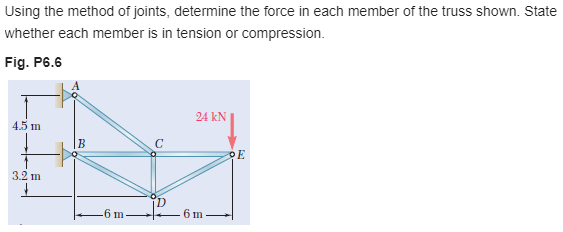

[https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-6P-solution-9780077687304](https://www.chegg.com/homework-help/Vector-Mechanics-for-Engineers-Statics-11th-edition-chapter-6-problem-6P-solution-9780077687304) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# member data

E = sym('E');
A = sym('A');
thetaAC = atand(sym(4.5/6))*u.deg;
thetaBD = atand(sym(3.2/6))*u.deg;
thetaDE = thetaBD;

# truss

t = Truss;
t = t.add('reaction', {'Rax' 'Ray'}, [0 0]);
t = t.add('reaction', {'Rbx' 'Rby'}, [0 -4.5]*u.m);
t = t.add('concentrated', [0 -24]*u.kN, [12 -4.5]*u.m);
t = t.add('joint', 'A', [0 0]);
t = t.add('joint', 'B', [0 -4.5]*u.m);
t = t.add('joint', 'C', [6 -4.5]*u.m);
t = t.add('joint', 'D', [6 -7.7]*u.m);
t = t.add('joint', 'E', [12 -4.5]*u.m);
t = t.add('member', 'Fac', [0 0], [6 -4.5]*u.m);
t = t.add('member', 'Fbc', [0 -4.5]*u.m, [6 -4.5]*u.m);
t = t.add('member', 'Fce', [6 -4.5]*u.m, [12 -4.5]*u.m);
t = t.add('member', 'Fde', [6 -7.7]*u.m, [12 -4.5]*u.m);
t = t.add('member', 'Fbd', [0 -4.5]*u.m, [6 -7.7]*u.m);
t = t.add('member', 'Fcd', [6 -4.5]*u.m, [6 -7.7]*u.m);

# solution

[us ua fs fa rs ra] = t.solve('factor'); %#ok
ua_vpa = vpa(ua) %#ok

$$ua\_vpa = \left(\begin{array}{cc} u_{1} & 0\\ v_{1} & 0\\ u_{2} & 0\\ v_{2} & 0\\ u_{3} & -\frac{114.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{3} & -\frac{1152.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{4} & -\frac{1089.36}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{4} & -\frac{1305.6}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{5} & \frac{156.0}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{5} & -\frac{4377.6}{A\,\text{E}}\,\mathrm{kN}\,m \end{array}\right)$$

fa

$$fa = \left(\begin{array}{cc} \mathrm{Fac} & 80\,\mathrm{kN}\\ \mathrm{Fbc} & -19\,\mathrm{kN}\\ \mathrm{Fbd} & -51\,\mathrm{kN}\\ \mathrm{Fcd} & 48\,\mathrm{kN}\\ \mathrm{Fce} & 45\,\mathrm{kN}\\ \mathrm{Fde} & -51\,\mathrm{kN} \end{array}\right)$$

ra

$$ra = \left(\begin{array}{cc} \mathrm{Rax} & -64\,\mathrm{kN}\\ \mathrm{Ray} & 48\,\mathrm{kN}\\ \mathrm{Rbx} & 64\,\mathrm{kN}\\ \mathrm{Rby} & -24\,\mathrm{kN} \end{array}\right)$$

# clean up

setassum(old_assum, 'clear');
clear ua_vpa old_assum;